# How photons become electrons and preserve the Poisson distribution

## The Poisson distribution

The Poisson distribution describes the statistics of a series of 'events'. For light an event is the arrival of a photon. 

The defining property of a Poisson distribution is that the chance of an event is the same at each small interval of time. 

Suppose that for each small unit of time, $\delta T$ the probability that a photon will arrive is constant, $\rho$. 

deltaT    = 1e-3;     % A millisecond
rho       = 1e-1;     % Chance of a photon in deltaT
T = deltaT:deltaT:1;  % Time samples over 1 sec

We can simulate the probably of an event happening or not using binomial distribution. 

Here is a plot with a line at each moments when there is (1) or is not (0) a photon.

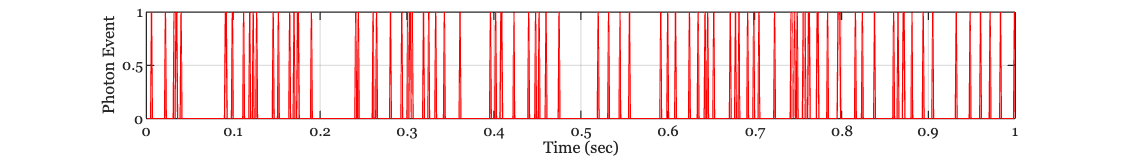

photons = binornd(1,rho,length(T),1);  % The binomial random distribution
f = ieFigure; 
plot(T,photons);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)'); ylabel('Photon Event'); grid on

fprintf('In a second, there were %d photons\n',sum(photons));

In a second, there were 94 photons


## Photon to electron conversion

At the sensor, an event is when a photon creates an electron. For a CMOS or CCD image sensor, each photon turns into one electron or no electrons.  

Suppose the probability of a photon generating an electron is $\epsilon$.  Let's set epsilon to one half, as an example.

epsilon = 0.5;

The probability of conversion is the same whenever the photon arrives. Here is the probability of the conversion, which is also a Poisson distribution.

eConversion = binornd(1,epsilon,length(T),1);

This is not worth plotting because with $\epsilon$ so large.  The graph of eConversion will just look like a solid red square.  We will have an electron in the interval $\delta T$ if 

- There is a photon in that interval, and 

- The electron conversion value is 1.

The probability is the same in each little time interval, and thus the whole calculation is Poisson.

electrons = photons .* eConversion;

Here is a plot of the electrons.  This is a subset of the times when there is a photon

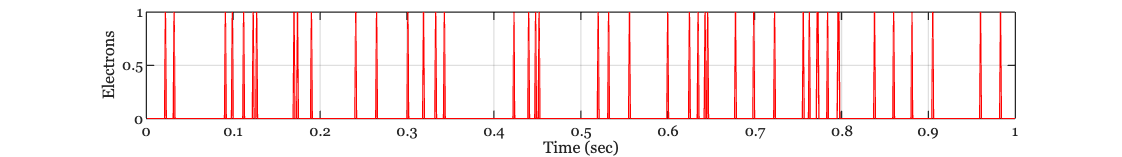

f = ieFigure; 
plot(T,electrons);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)'); ylabel('Electrons'); grid on

fprintf('Combining photons with conversion likelihood, there were %d electrons\n',sum(electrons));

Combining photons with conversion likelihood, there were 44 electrons


## Equivalent calculation

We do not have to do the calculation in two steps.  The calculation would be the same distribution if we combine the two probabilities up front. 

electrons2 = binornd(1,rho*epsilon,length(T),1);

This produces the same results as doing the calculation in two steps.

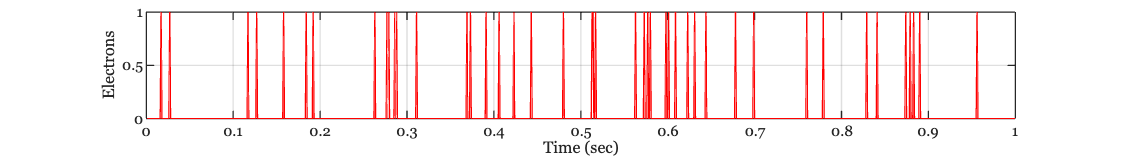

f = ieNewGraphWin; plot(T,electrons2);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)');
ylabel('Electrons'); grid on

fprintf('The alternative calculation - use the binomial with the combined probabilities.\nThere were %d electrons\n',sum(electrons));

The alternative calculation - use the binomial with the combined probabilities.
There were 44 electrons
